# `Exp-06: Solving linear differential equations using 'dsolve'`

## `Table of Contents:`

- Question-1

- Question-2

- Question-3

Question-1

Solve: $\frac{\textrm{dy}}{\textrm{dx}}$ =$x+y\;\;\textrm{with}\;y\left(0\right)=0\;\;\textrm{and}$ store the solution as Solution(x). What is the value of the solution at $x=1\ldotp 5\;$and Plot the solution in the interval [0,1.5]

syms y(x)
DiffEq1=diff(y,x)==x+y;
Sol(x)=dsolve(DiffEq1)

$$Sol(x) = C_{1}\,{\mathrm{e}}^{x}-x-1$$

ic1=y(0)==0;
Solution(x)=dsolve(DiffEq1,ic1)

$$Solution(x) = {\mathrm{e}}^{x}-x-1$$

S_15=Solution(1.5)

$$S\_15 = {\mathrm{e}}^{3/2}-\frac{5}{2}$$

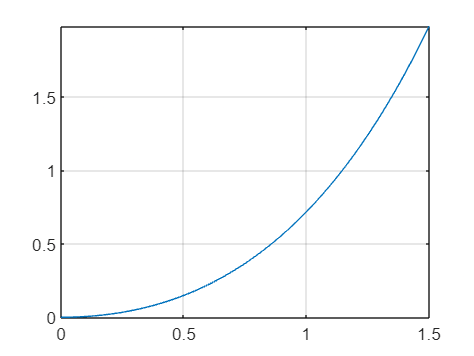

fplot(Solution,[0,1.5])
grid on

Question-2

Solve: $\frac{\textrm{dy}}{\textrm{dx}}+\frac{y}{x}=e^x$ and Plot the solution in the interval [1,5]

clear
syms y(x)
DiffEq2=diff(y,x)==exp(x);
Sol(x)=dsolve(DiffEq2)

$$Sol(x) = C_{1}+{\mathrm{e}}^{x}$$

ic1=y(0)==0;
Solution(x)=dsolve(DiffEq2,ic1)

$$Solution(x) = {\mathrm{e}}^{x}-1$$

S=vpa(Solution(5),5)

$$S = 147.41$$

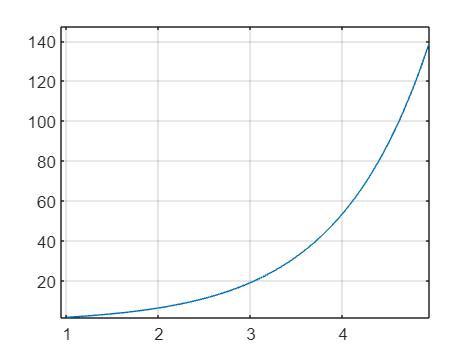

fplot(Solution,[1,5])
grid on

xlim([0.94 4.94])
ylim([2 147])

Question-3

Solve: $\left(1+x^2 \right)\textrm{dy}+\left(2\textrm{xy}-4x^3 \right)\textrm{dx}$ with $y\left(0\right)=1$.Store the solution as solution(x). Find the solution(1) & store it as S_1. Plot the graph in [-1,1].

clear all
syms y(x)
DE3=(1+x^2)*diff(y,x)+(2*x*y-4*x^3)==0

$$DE3(x) = \left(x^{2}+1\right)\,\frac{\partial }{\partial x}y\left(x\right)+2\,x\,y\left(x\right)-4\,x^{3}=0$$

sol(x)=dsolve(DE3)

$$sol(x) = -\frac{C_{1}-x^{4}}{x^{2}+1}$$

ic3=y(0)==1;
solution(x)=dsolve(DE3,ic3)

$$solution(x) = \frac{x^{4}+1}{x^{2}+1}$$

S_1=solution(1)

$$S\_1 = 1$$

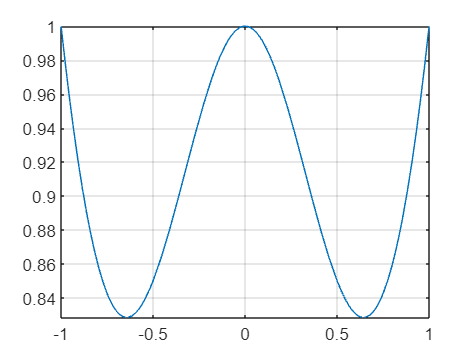

fplot(solution,[-1,1])
grid on